# Ver 3 Network:

- Presynaptic neuron # fixed;

- Boundaries tape back

- LGN: Phase variant

- Adding complex cells

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Figures/Demo071021/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Figures/Demo042221/'];
addpath(DataFolder)

First read old network structure, get our desired Numbers of presyn neurons

% load('NtWk_Archit.mat')
% E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
% I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
% 
% N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); %*0.75
% N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %*0.75 Plan A:Original

Then use the new function to generate new network stucture


%% If now, we start computation below...
% Frst setup network
N_HC = 3;
% Number of E and I neurons
n_S_HC = 45; n_C_HC = 30; n_I_HC = 31; % per side of HC
N_S = n_S_HC^2 * N_HC^2; % neuron numbers In all
N_C = n_C_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
N_E = N_S+N_C; CplxR = N_C/N_E;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_S = Size_HC/n_S_HC; Size_C = Size_HC/n_C_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnS.X,NnS.Y] = V1Field_Generation(N_HC,1:N_S,'e',n_S_HC,n_I_HC);
[NnC.X,NnC.Y] = V1Field_Generation(N_HC,1:N_C,'e',n_C_HC,n_I_HC);
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');
%NnE.X = [NnS.X,NnC.X]; NnE.Y = [NnS.Y,NnC.Y];

We are fixing boundary effect by connecting neurons to similar ODs

% Extended spatial indexes of E and I neurons (1HC each side)
Nex_S = n_S_HC^2 * (N_HC+2)^2; % neuron numbers In all
Nex_C = n_C_HC^2 * (N_HC+2)^2; 
Nex_I = n_I_HC^2 * (N_HC+2)^2;
[NnSex.X,NnSex.Y] = V1Field_Generation(N_HC+2,1:Nex_S,'e',n_S_HC,n_I_HC);
[NnCex.X,NnCex.Y] = V1Field_Generation(N_HC+2,1:Nex_C,'e',n_C_HC,n_I_HC);
[NnIex.X,NnIex.Y] = V1Field_Generation(N_HC+2,1:Nex_I,'i');

Now select complx cells

N_EE = 195; N_EI = 85; %*0.75
N_IE = 844; N_II = 84; %*0.75 Plan A:Original

CplxNEIncr = 250/N_EE;
EcplxInd = ismember(1:N_E, N_S+1:N_E); 

N_SS = N_EE * (1-CplxR);            N_SC = N_EE * (CplxR); 
N_CS = N_EE * (1-CplxR)*CplxNEIncr; N_CC = N_EE * (CplxR)*CplxNEIncr;
N_SI = N_EI;                        N_CI = N_EI; 
N_IS = N_IE * (1-CplxR);            N_IC = N_IE * (CplxR); 

## Get a mapping between original and extended spatial indexs

% From original to extended
SMap_Ori2Ext = find(NnSex.X>n_S_HC & NnSex.X<=4*n_S_HC ...
                  & NnSex.Y>n_S_HC & NnSex.Y<=4*n_S_HC);
CMap_Ori2Ext = find(NnCex.X>n_C_HC & NnCex.X<=4*n_C_HC ...
                  & NnCex.Y>n_C_HC & NnCex.Y<=4*n_C_HC);
IMap_Ori2Ext = find(NnIex.X>n_I_HC & NnIex.X<=4*n_I_HC ...
                  & NnIex.Y>n_I_HC & NnIex.Y<=4*n_I_HC);
% from extended back to original: fold
% E
SMap_Ext2Ori = FoldExMap2Ori(NnSex,NnS,SMap_Ori2Ext,N_S,n_S_HC);
CMap_Ext2Ori = FoldExMap2Ori(NnCex,NnC,CMap_Ori2Ext,N_C,n_C_HC);
% I
IMap_Ext2Ori = FoldExMap2Ori(NnIex,NnI,IMap_Ori2Ext,N_I,n_I_HC);
% determine connections between E, I sparse metrices containing 0 or 1.
% Row_i Column_j means neuron j projects to neuron i add periodic boundary
% EE
C_SS_Fix_Bd = ConnectionMat_FB_SimCplx(N_S,NnSex,Size_S, SMap_Ori2Ext, 1:N_S,...% 
                                       N_S,NnSex,Size_S, SMap_Ext2Ori, 1:N_S,...
                                       Peak_EE,SD_E,Dist_LB,1, round(N_SS));

Elapsed time is 9.465025 seconds.


C_SC_Fix_Bd = ConnectionMat_FB_SimCplx(N_S,NnSex,Size_S, SMap_Ori2Ext, 1:N_S,...% 
                                       N_C,NnCex,Size_C, CMap_Ext2Ori, 1:N_C,...
                                       Peak_EE,SD_E,Dist_LB,0, round(N_SC));

Elapsed time is 5.366377 seconds.


C_CS_Fix_Bd = ConnectionMat_FB_SimCplx(N_C,NnCex,Size_C, CMap_Ori2Ext, 1:N_C,...% 
                                       N_S,NnSex,Size_S, SMap_Ext2Ori, 1:N_S,...
                                       Peak_EE,SD_E,Dist_LB,0, round(N_CS));

Elapsed time is 4.648897 seconds.


C_CC_Fix_Bd = ConnectionMat_FB_SimCplx(N_C,NnCex,Size_C, CMap_Ori2Ext, 1:N_C,...% 
                                       N_C,NnCex,Size_C, CMap_Ext2Ori, 1:N_C,...
                                       Peak_EE,SD_E,Dist_LB,1, round(N_CC));

Elapsed time is 2.479007 seconds.


C_EE_Fix_Bd = [C_SS_Fix_Bd, C_SC_Fix_Bd; C_CS_Fix_Bd, C_CC_Fix_Bd];
% EI
C_SI_Fix_Bd = ConnectionMat_FB_SimCplx(N_S,NnSex,Size_S, SMap_Ori2Ext, 1:N_S,...
                                       N_I,NnIex,Size_I, IMap_Ext2Ori, 1:N_I,...
                                       Peak_I,SD_I,Dist_LB,0, round(N_SI));

Elapsed time is 6.031761 seconds.


C_CI_Fix_Bd = ConnectionMat_FB_SimCplx(N_C,NnCex,Size_C, CMap_Ori2Ext, 1:N_C,...
                                       N_I,NnIex,Size_I, IMap_Ext2Ori, 1:N_I,...
                                       Peak_I,SD_I,Dist_LB,0, round(N_CI));

Elapsed time is 2.655880 seconds.


C_EI_Fix_Bd = [C_SI_Fix_Bd; C_CI_Fix_Bd];
% IE
C_IS_Fix_Bd = ConnectionMat_FB_SimCplx(N_I,NnIex,Size_I, IMap_Ori2Ext, 1:N_I,...
                                       N_S,NnSex,Size_S, SMap_Ext2Ori, 1:N_S,...
                                       Peak_I,SD_E,Dist_LB,0, round(N_IS));

Elapsed time is 8.370018 seconds.


C_IC_Fix_Bd = ConnectionMat_FB_SimCplx(N_I,NnIex,Size_I, IMap_Ori2Ext, 1:N_I,...
                                       N_C,NnCex,Size_C, CMap_Ext2Ori, 1:N_C,...
                                       Peak_I,SD_E,Dist_LB,0, round(N_IC));

Elapsed time is 4.284789 seconds.


C_IE_Fix_Bd = [C_IS_Fix_Bd, C_IC_Fix_Bd];
% II
C_II_Fix_Bd = ConnectionMat_Fix_Boundary(N_I,NnIex,Size_I, IMap_Ori2Ext,...
                                         N_I,NnIex,Size_I, IMap_Ext2Ori,...
                                         Peak_I,SD_I,Dist_LB,1, round(N_II));

Elapsed time is 2.785811 seconds.



CMatAll = struct('C_EE_Fix_Bd',C_EE_Fix_Bd,...
                 'C_EI_Fix_Bd',C_EI_Fix_Bd,...
                 'C_IE_Fix_Bd',C_IE_Fix_Bd,...
                 'C_II_Fix_Bd',C_II_Fix_Bd);

### Checking presyn neurons to boundary neurons. Can jump

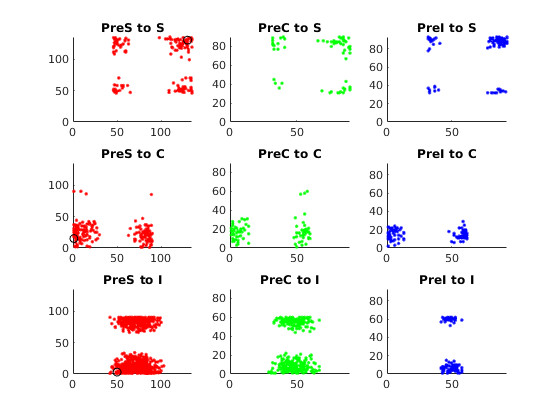

figure
% S cell as post
SX = 130; SY = 130;
SInd = find(NnS.X == SX & NnS.Y == SY);
PreSInd = find(C_SS_Fix_Bd(SInd,:));
PreCInd = find(C_SC_Fix_Bd(SInd,:));
PreIInd = find(C_SI_Fix_Bd(SInd,:));

subplot 331
hold on
%imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnS.X(PreSInd),NnS.Y(PreSInd), 'r.')
scatter(SX,SY,'kO')
set(gca,'YDir','normal')
axis([0 n_S_HC * N_HC 0 n_S_HC * N_HC])
title('PreS to S')

subplot 332
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnC.X(PreCInd),NnC.Y(PreCInd), 'g.')
set(gca,'YDir','normal')
axis([0 n_C_HC * N_HC 0 n_C_HC * N_HC])
title('PreC to S')

subplot 333
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to S')

% C cell as post
CX = 1; CY = 15;
CInd = find(NnC.X == CX & NnC.Y == CY);
PreSInd = find(C_CS_Fix_Bd(CInd,:));
PreCInd = find(C_CC_Fix_Bd(CInd,:));
PreIInd = find(C_CI_Fix_Bd(CInd,:));

subplot 334
hold on
%imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnS.X(PreSInd),NnS.Y(PreSInd), 'r.')
scatter(CX,CY,'kO')
set(gca,'YDir','normal')
axis([0 n_S_HC * N_HC 0 n_S_HC * N_HC])
title('PreS to C')

subplot 335
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnC.X(PreCInd),NnC.Y(PreCInd), 'g.')
set(gca,'YDir','normal')
axis([0 n_C_HC * N_HC 0 n_C_HC * N_HC])
title('PreC to C')

subplot 336
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to C')

% I cell as post
IX = 50; IY = 3;
IInd = find(NnI.X == IX & NnI.Y == IY);
PreSInd = find(C_IS_Fix_Bd(IInd,:));
PreCInd = find(C_IC_Fix_Bd(IInd,:));
PreIInd = find(C_II_Fix_Bd(IInd,:));

subplot 337
hold on
%imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnS.X(PreSInd),NnS.Y(PreSInd), 'r.')
scatter(IX,IY,'kO')
set(gca,'YDir','normal')
axis([0 n_S_HC * N_HC 0 n_S_HC * N_HC])
title('PreS to I')

subplot 338
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnC.X(PreCInd),NnC.Y(PreCInd), 'g.')
set(gca,'YDir','normal')
axis([0 n_C_HC * N_HC 0 n_C_HC * N_HC])
title('PreC to I')

subplot 339
hold on
%imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to I')

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.6;  % was 1.5
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Network Simulation: BG

Elapsed time is 5.584281 seconds.
Elapsed time is 8.338473 seconds.
Elapsed time is 10.987537 seconds.
Elapsed time is 13.828542 seconds.
Elapsed time is 16.577274 seconds.
Elapsed time is 19.386274 seconds.
Elapsed time is 22.143767 seconds.
Elapsed time is 24.967936 seconds.


S_EE = 0.024, S_EI = 0.0384, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

Elapsed time is 28.095315 seconds.
Elapsed time is 31.019936 seconds.
Elapsed time is 33.988611 seconds.
Elapsed time is 36.960381 seconds.
Elapsed time is 40.088324 seconds.
Elapsed time is 43.175864 seconds.
Elapsed time is 46.251767 seconds.
Elapsed time is 49.285964 seconds.
Elapsed time is 52.624581 seconds.
Elapsed time is 55.894576 seconds.


S_EE = 0.024, S_EI = 0.0384, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

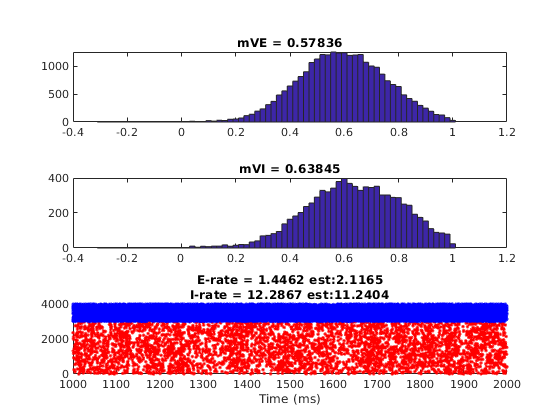

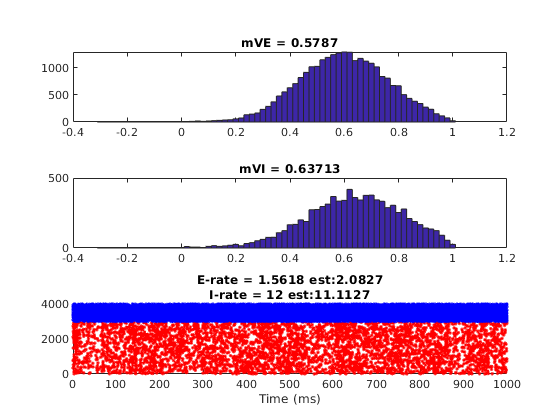

Elapsed time is 59.519463 seconds.


%% Network Simulation
T = 2000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.5; N_EEDly = floor(T_EEDly/dt);
T_IEDly = 0.5; N_IEDly = floor(T_IEDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Compute Neuron Ind
% E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
% 
% I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
% 
% N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
% N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Create sliding windows
sampleT = 200;
Sliding = 100;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
[InEs, InIs] = LargeNW_LoadIniState('Initials_L6.mat', N_E, N_I);
RefTimeE = InEs.RefTimeE; VE = InEs.VE; SpE = InEs.SpE; GE_ampa_R = InEs.GE_ampa_R; GE_nmda_R = InEs.GE_nmda_R; GE_gaba_R = InEs.GE_gaba_R;
GE_ampa_D = InEs.GE_ampa_D; GE_nmda_D = InEs.GE_nmda_D; GE_gaba_D = InEs.GE_gaba_D;
RefTimeI = InIs.RefTimeI; VI = InIs.VI; SpI = InIs.SpI; GI_ampa_R = InIs.GI_ampa_R; GI_nmda_R = InIs.GI_nmda_R; GI_gaba_R = InIs.GI_gaba_R;
GI_ampa_D = InIs.GI_ampa_D; GI_nmda_D = InIs.GI_nmda_D; GI_gaba_D = InIs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = sparse(N_I,N_IEDly);
%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

E_Ind = 10000:13000; I_Ind = 3300:4300;
tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd,oIEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver2_EEnIEDelay(...
        RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,IEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        scatterE = find(ismember(E_Sp(:,1),E_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
        f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    S_EL6,S_IL6,rE_L6,rI_L6,...
                                                    gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
        title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
        ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        %close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(E_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(E_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
        toc
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
    if sum(isnan(oVE))>0.80*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    
    % the end of iteration
end

toc

Elapsed time is 59.524406 seconds.



NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [E_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop

## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_S = zeros(size(NnS.X),'single');
OD_SMap = zeros(n_S_HC*N_HC,'single');
for NeuInd = 1:length(NnS.X)
OD_S(NeuInd) = OrientDom(ODNum,NnS.X(NeuInd),NnS.Y(NeuInd),n_S_HC);
OD_SMap(NnS.Y(NeuInd),NnS.X(NeuInd)) = OD_S(NeuInd);
end

OD_C = zeros(size(NnC.X),'single');
OD_CMap = zeros(n_C_HC*N_HC,'single');
for NeuInd = 1:length(NnC.X)
OD_C(NeuInd) = OrientDom(ODNum,NnC.X(NeuInd),NnC.Y(NeuInd),n_C_HC);
OD_CMap(NnC.Y(NeuInd),NnC.X(NeuInd)) = OD_C(NeuInd);
end
OD_E = [OD_S, OD_C];

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 10; % 2Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
PhaseFRS = [90 67.5 45 67.5,    0  22.5 45 22.5] *4/1e3 * StimulusFac;
PhaseFRC = [90 67.5 45 67.5,    0  22.5 45 22.5] *1.0/1e3 * StimulusFac;
lambda_EOn_drive  = [PhaseFRS(OD_S),PhaseFRC(OD_C)]'; % Should do another for Cplx cells
lambda_EOff_drive = [PhaseFRS(OD_S+ODNum),PhaseFRC(OD_C+ODNum)]';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive_Pre = 45 *4/1e3 * StimulusFac;
lambda_I_drive_Pre = 45 *4/1e3 * StimulusFac;

L6E_Drive = [50 35 20 35]*50/1e3 * StimulusFac;
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';


% Making Poisson here/Reading
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);


Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
% SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = .5; N_EIDly = floor(T_EIDly/dt);
% The initial states, for more simulation 
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
Fields = {'RefTimeE','VE','SpE','GE_ampa_R','GE_nmda_R','GE_gaba_R','GE_ampa_D','GE_nmda_D','GE_gaba_D',...
          'RefTimeI','VI','SpI','GI_ampa_R','GI_nmda_R','GI_gaba_R','GI_ampa_D','GI_nmda_D','GI_gaba_D'};
InSStr = cell2struct(EndState(1:length(Fields)), Fields, 2);
[InEs, InIs] = LargeNW_LoadIniState(InSStr, N_E, N_I);
RefTimeE = InEs.RefTimeE; VE = InEs.VE; SpE = InEs.SpE; GE_ampa_R = InEs.GE_ampa_R; GE_nmda_R = InEs.GE_nmda_R; GE_gaba_R = InEs.GE_gaba_R;
GE_ampa_D = InEs.GE_ampa_D; GE_nmda_D = InEs.GE_nmda_D; GE_gaba_D = InEs.GE_gaba_D;
RefTimeI = InIs.RefTimeI; VI = InIs.VI; SpI = InIs.SpI; GI_ampa_R = InIs.GI_ampa_R; GI_nmda_R = InIs.GI_nmda_R; GI_gaba_R = InIs.GI_gaba_R;
GI_ampa_D = InIs.GI_ampa_D; GI_nmda_D = InIs.GI_nmda_D; GI_gaba_D = InIs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = ones(N_I,N_IEDly);
EIDlyRcd = ones(N_E,N_EIDly);
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end

% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
% SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

Bug here: Though I defined AdjlgnE for every step, it is used only every 100ms...

So: 250on/250off are mixed here...

for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % Zero: Use Phase vec to determine different lgn phases for E neurons
    PhaseE = mod(PhaseE + dt,tMod);      
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        tt = 0:dt:InpWin-dt;
        AdjlgnE = PhaseFRS(floor(mod(PhaseE + tt, tMod)/MaxOnPhase)*ODNum + OD_E');
        AdjlgnE(EcplxInd,:) = PhaseFRC(floor(mod(PhaseE(EcplxInd) + tt, tMod)/MaxOnPhase)*ODNum + OD_E(EcplxInd)');
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE/lambda_E_drive_Pre + AdjlgnE*dt*LGNCurInp)...
                             + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                             + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive_Pre*dt*LGNCurInp) ...
                             + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                             + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                                        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                                                        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                                        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                                        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;

    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.1; % Can't be too small for multiple phases
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GE_ETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GE_ITemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GI_ETemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GI_ITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs = I_Sp;
        
        NWTrace(SampleInd).GE_I = GE_ITemp;
        NWTrace(SampleInd).GE_E = GE_ETemp;
        NWTrace(SampleInd).GI_I = GI_ITemp;
        NWTrace(SampleInd).GI_E = GI_ETemp;
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E
        FrESNow = sum(ismember(E_Sp(:,1), find(~EcplxInd)))/N_S/sampleT*1000
        FrECNow = sum(ismember(E_Sp(:,1), find(EcplxInd)))/N_C/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        % Precompute GE GI
        GE_I = 1/(tau_gaba_D-tau_gaba_R) * (GE_gaba_D - GE_gaba_R); % S_EI is included in amplitude of GE_gaba
        GE_E = 1/(tau_ampa_D-tau_ampa_R) * (GE_ampa_D - GE_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GE_nmda_D - GE_nmda_R); %                       

        GI_I = 1/(tau_gaba_D-tau_gaba_R) * (GI_gaba_D - GI_gaba_R); % S_EI is included in amplitude of GE_gaba
        GI_E = 1/(tau_ampa_D-tau_ampa_R) * (GI_ampa_D - GI_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GI_nmda_D - GI_nmda_R); %                       
        GE_ITemp(:,mVRecordInd) = GE_I;
        GE_ETemp(:,mVRecordInd) = GE_E;
        GI_ITemp(:,mVRecordInd) = GI_I;
        GI_ETemp(:,mVRecordInd) = GI_E;
        %record loop goes forward
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = [sprintf('DriveWkSp_Cplx_SCSepa_%dHz',LGNFreq) num2str(TSec) 's.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd};
save([SaveFolder text],'NWTrace','EndState','PhaseE','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
end

SampleInd = 2

FrESNow = 11.9122

FrECNow = 26.3432

FrINow = 65.4966

Elapsed time is 2.555342 seconds.


SampleInd = 3

FrESNow = 8.6661

FrECNow = 12.9605

FrINow = 50.9839

Elapsed time is 3.958661 seconds.


SampleInd = 4

FrESNow = 11.6719

FrECNow = 20.0864

FrINow = 61.0660

Elapsed time is 6.422418 seconds.


SampleInd = 5

FrESNow = 9.7218

FrECNow = 14.8148

FrINow = 54.3600

Elapsed time is 7.995592 seconds.


SampleInd = 6

FrESNow = 11.6379

FrECNow = 21.3506

FrINow = 62.4604

Elapsed time is 10.420299 seconds.


SampleInd = 7

FrESNow = 9.9347

FrECNow = 16.3111

FrINow = 56.1568

Elapsed time is 12.032158 seconds.


SampleInd = 8

FrESNow = 11.2428

FrECNow = 18.5852

FrINow = 59.4473

Elapsed time is 14.504278 seconds.


SampleInd = 9

FrESNow = 11.2000

FrECNow = 18.9926

FrINow = 59.8774

Elapsed time is 16.190613 seconds.


SampleInd = 10

FrESNow = 10.4329

FrECNow = 15.8519

FrINow = 56.8551

Elapsed time is 18.459202 seconds.


SampleInd = 11

FrESNow = 11.5676

FrECNow = 20.9481

FrINow = 62.0835

Elapsed time is 20.158949 seconds.


SampleInd = 12

FrESNow = 10.3396

FrECNow = 15.0864

FrINow = 55.5347

Elapsed time is 22.474858 seconds.


SampleInd = 13

FrESNow = 10.8927

FrECNow = 19.1630

FrINow = 59.6555

Elapsed time is 24.129356 seconds.


SampleInd = 14

FrESNow = 10.9575

FrECNow = 19.4469

FrINow = 60.1318

Elapsed time is 26.505901 seconds.


SampleInd = 15

FrESNow = 10.6392

FrECNow = 16.3778

FrINow = 57.1997

Elapsed time is 28.131260 seconds.


SampleInd = 16

FrESNow = 11.1243

FrECNow = 19.5605

FrINow = 60.3584

Elapsed time is 30.570511 seconds.


SampleInd = 17

FrESNow = 11.0628

FrECNow = 20.6346

FrINow = 61.8361

Elapsed time is 32.348145 seconds.


SampleInd = 18

FrESNow = 10.6019

FrECNow = 15.4420

FrINow = 56.5568

Elapsed time is 34.670629 seconds.


SampleInd = 19

FrESNow = 11.4513

FrECNow = 23.2395

FrINow = 64.3543

Elapsed time is 36.440284 seconds.


SampleInd = 20

FrESNow = 9.8557

FrECNow = 12.7062

FrINow = 53.2593

Elapsed time is 38.719114 seconds.


SampleInd = 21

FrESNow = 11.1177

FrECNow = 19.7605

FrINow = 60.6382

Elapsed time is 40.355390 seconds.


Elapsed time is 40.356178 seconds.


SampleInd = 22

FrESNow = 11.2955

FrECNow = 19.8642

FrINow = 61.0683

Elapsed time is 2.442627 seconds.


SampleInd = 23

FrESNow = 10.3298

FrECNow = 17.5481

FrINow = 57.9396

Elapsed time is 4.043512 seconds.


SampleInd = 24

FrESNow = 11.6258

FrECNow = 20.2642

FrINow = 61.7713

Elapsed time is 6.433439 seconds.


SampleInd = 25

FrESNow = 9.8634

FrECNow = 16.1605

FrINow = 56.1383

Elapsed time is 7.975362 seconds.


SampleInd = 26

FrESNow = 11.6148

FrECNow = 20.9827

FrINow = 62.4350

Elapsed time is 10.429030 seconds.


SampleInd = 27

FrESNow = 10.1235

FrECNow = 16.2741

FrINow = 56.6840

Elapsed time is 12.028257 seconds.


SampleInd = 28

FrESNow = 11.2626

FrECNow = 20.0741

FrINow = 60.8093

Elapsed time is 14.309944 seconds.


SampleInd = 29

FrESNow = 10.2738

FrECNow = 16.2988

FrINow = 56.6701

Elapsed time is 15.863679 seconds.


SampleInd = 30

FrESNow = 10.6612

FrECNow = 16.7852

FrINow = 57.2552

Elapsed time is 18.229843 seconds.


SampleInd = 31

FrESNow = 11.0431

FrECNow = 22.1852

FrINow = 62.7587

Elapsed time is 19.988564 seconds.


SampleInd = 32

FrESNow = 10.6864

FrECNow = 15.1062

FrINow = 56.3533

Elapsed time is 22.182441 seconds.


SampleInd = 33

FrESNow = 11.1144

FrECNow = 24.8765

FrINow = 64.8676

Elapsed time is 23.960750 seconds.


SampleInd = 34

FrESNow = 10.1761

FrECNow = 14.0667

FrINow = 55.0954

Elapsed time is 26.229956 seconds.


SampleInd = 35

FrESNow = 11.5654

FrECNow = 22.3728

FrINow = 63.3437

Elapsed time is 28.025765 seconds.


SampleInd = 36

FrESNow = 10.4099

FrECNow = 15.9951

FrINow = 56.7858

Elapsed time is 30.387699 seconds.


SampleInd = 37

FrESNow = 10.8664

FrECNow = 19.3753

FrINow = 59.9445

Elapsed time is 32.096468 seconds.


SampleInd = 38

FrESNow = 10.6897

FrECNow = 16.4049

FrINow = 57.2251

Elapsed time is 34.429443 seconds.


SampleInd = 39

FrESNow = 11.1155

FrECNow = 19.9358

FrINow = 60.8325

Elapsed time is 36.130243 seconds.


SampleInd = 40

FrESNow = 10.4911

FrECNow = 16.3630

FrINow = 57.0864

Elapsed time is 38.483182 seconds.


SampleInd = 41

FrESNow = 11.1682

FrECNow = 22.5556

FrINow = 63.2512

Elapsed time is 40.124322 seconds.


Elapsed time is 40.125059 seconds.


SampleInd = 42

FrESNow = 10.6524

FrECNow = 15.7185

FrINow = 56.8968

Elapsed time is 2.248929 seconds.


SampleInd = 43

FrESNow = 10.8894

FrECNow = 20.7309

FrINow = 61.5354

Elapsed time is 3.957415 seconds.


SampleInd = 44

FrESNow = 10.7698

FrECNow = 16.1432

FrINow = 57.0656

Elapsed time is 6.193346 seconds.


SampleInd = 45

FrESNow = 11.1177

FrECNow = 21.4840

FrINow = 62.4835

Elapsed time is 7.968035 seconds.


SampleInd = 46

FrESNow = 10.7929

FrECNow = 15.8049

FrINow = 57.2552

Elapsed time is 10.236591 seconds.


SampleInd = 47

FrESNow = 10.7687

FrECNow = 19.4864

FrINow = 60.2058

Elapsed time is 11.973020 seconds.


SampleInd = 48

FrESNow = 10.7160

FrECNow = 16.6593

FrINow = 57.3777

Elapsed time is 14.225652 seconds.


SampleInd = 49

FrESNow = 11.1056

FrECNow = 20.3086

FrINow = 61.2533

Elapsed time is 15.898193 seconds.


SampleInd = 50

FrESNow = 10.7863

FrECNow = 17.9185

FrINow = 58.3883

Elapsed time is 18.200081 seconds.


SampleInd = 51

FrESNow = 11.0837

FrECNow = 21.2988

FrINow = 61.9517

Elapsed time is 19.880795 seconds.


SampleInd = 52

FrESNow = 11.0299

FrECNow = 19.3407

FrINow = 60.5411

Elapsed time is 22.167504 seconds.


SampleInd = 53

FrESNow = 10.5503

FrECNow = 17.3679

FrINow = 58.2102

Elapsed time is 23.791442 seconds.


SampleInd = 54

FrESNow = 10.8203

FrECNow = 17.2790

FrINow = 58.2611

Elapsed time is 26.052526 seconds.


SampleInd = 55

FrESNow = 10.8620

FrECNow = 20.7827

FrINow = 61.4799

Elapsed time is 27.792649 seconds.


SampleInd = 56

FrESNow = 10.9641

FrECNow = 17.4469

FrINow = 58.1848

Elapsed time is 30.066743 seconds.


SampleInd = 57

FrESNow = 10.4812

FrECNow = 21.5333

FrINow = 61.5424

Elapsed time is 31.749677 seconds.


SampleInd = 58

FrESNow = 11.1089

FrECNow = 18.0790

FrINow = 59.4196

Elapsed time is 34.031765 seconds.


SampleInd = 59

FrESNow = 10.4066

FrECNow = 18.7185

FrINow = 59.1745

Elapsed time is 35.580939 seconds.


SampleInd = 60

FrESNow = 11.1407

FrECNow = 18.6420

FrINow = 59.6138

Elapsed time is 37.829453 seconds.


SampleInd = 61

FrESNow = 10.3550

FrECNow = 19.8815

FrINow = 60.0162

Elapsed time is 39.400686 seconds.


Elapsed time is 39.401417 seconds.


SampleInd = 62

FrESNow = 10.7567

FrECNow = 16.7160

FrINow = 57.3569

Elapsed time is 2.309461 seconds.


SampleInd = 63

FrESNow = 10.9399

FrECNow = 22.5778

FrINow = 63.0316

Elapsed time is 4.057530 seconds.


SampleInd = 64

FrESNow = 10.3923

FrECNow = 16.0247

FrINow = 56.9869

Elapsed time is 6.322064 seconds.


SampleInd = 65

FrESNow = 10.3693

FrECNow = 15.4296

FrINow = 55.5093

Elapsed time is 7.878599 seconds.


SampleInd = 66

FrESNow = 12.2458

FrECNow = 26.3185

FrINow = 67.3303

Elapsed time is 10.399000 seconds.


SampleInd = 67

FrESNow = 9.4683

FrECNow = 13.7877

FrINow = 54.2421

Elapsed time is 11.906247 seconds.


SampleInd = 68

FrESNow = 11.2845

FrECNow = 20.6988

FrINow = 61.5863

Elapsed time is 14.341933 seconds.


SampleInd = 69

FrESNow = 10.6272

FrECNow = 19.6988

FrINow = 60.2336

Elapsed time is 15.946714 seconds.


SampleInd = 70

FrESNow = 10.8181

FrECNow = 17.2321

FrINow = 58.1547

Elapsed time is 18.279198 seconds.


SampleInd = 71

FrESNow = 10.7084

FrECNow = 18.7062

FrINow = 59.1814

Elapsed time is 19.885739 seconds.


SampleInd = 72

FrESNow = 10.9805

FrECNow = 17.0593

FrINow = 58.2634

Elapsed time is 22.274450 seconds.


SampleInd = 73

FrESNow = 10.6239

FrECNow = 18.9753

FrINow = 59.4959

Elapsed time is 23.995590 seconds.


SampleInd = 74

FrESNow = 11.5534

FrECNow = 18.8198

FrINow = 60.1596

Elapsed time is 26.400472 seconds.


SampleInd = 75

FrESNow = 10.3309

FrECNow = 21.1580

FrINow = 61.3366

Elapsed time is 28.116711 seconds.


SampleInd = 76

FrESNow = 11.2154

FrECNow = 18.7235

FrINow = 60.3515

Elapsed time is 30.522834 seconds.


SampleInd = 77

FrESNow = 10.5723

FrECNow = 19.4049

FrINow = 60.4671

Elapsed time is 32.237733 seconds.


SampleInd = 78

FrESNow = 11.0387

FrECNow = 16.2049

FrINow = 57.3407

Elapsed time is 34.564251 seconds.


SampleInd = 79

FrESNow = 10.9959

FrECNow = 22.1605

FrINow = 62.7171

Elapsed time is 36.348842 seconds.


SampleInd = 80

FrESNow = 11.5259

FrECNow = 19.5457

FrINow = 61.1539

Elapsed time is 38.688433 seconds.


SampleInd = 81

FrESNow = 10.1377

FrECNow = 16.0765

FrINow = 56.9569

Elapsed time is 40.294923 seconds.


Elapsed time is 40.295641 seconds.


SampleInd = 82

FrESNow = 11.2143

FrECNow = 18.5531

FrINow = 59.9376

Elapsed time is 2.515452 seconds.


SampleInd = 83

FrESNow = 10.7018

FrECNow = 17.9802

FrINow = 58.7629

Elapsed time is 4.323599 seconds.


SampleInd = 84

FrESNow = 11.7432

FrECNow = 23.1580

FrINow = 64.7104

Elapsed time is 6.854734 seconds.


SampleInd = 85

FrESNow = 9.6604

FrECNow = 14.1062

FrINow = 54.2305

Elapsed time is 8.453744 seconds.


SampleInd = 86

FrESNow = 11.8606

FrECNow = 21.9630

FrINow = 63.0824

Elapsed time is 10.951973 seconds.


SampleInd = 87

FrESNow = 10.2639

FrECNow = 16.9185

FrINow = 57.4332

Elapsed time is 12.585866 seconds.


SampleInd = 88

FrESNow = 10.7632

FrECNow = 17.4099

FrINow = 58.1154

Elapsed time is 14.937387 seconds.


SampleInd = 89

FrESNow = 10.9191

FrECNow = 18.7704

FrINow = 59.5190

Elapsed time is 16.582604 seconds.


SampleInd = 90

FrESNow = 11.0222

FrECNow = 18.9160

FrINow = 59.8451

Elapsed time is 19.007510 seconds.


SampleInd = 91

FrESNow = 10.8368

FrECNow = 19.8049

FrINow = 60.6428

Elapsed time is 20.697578 seconds.


SampleInd = 92

FrESNow = 10.0412

FrECNow = 13.8173

FrINow = 54.3045

Elapsed time is 22.890791 seconds.


SampleInd = 93

FrESNow = 11.0036

FrECNow = 21.1827

FrINow = 61.6094

Elapsed time is 24.588575 seconds.


SampleInd = 94

FrESNow = 10.8071

FrECNow = 16.5383

FrINow = 57.3014

Elapsed time is 26.927386 seconds.


SampleInd = 95

FrESNow = 10.9366

FrECNow = 22.2864

FrINow = 62.5436

Elapsed time is 28.636775 seconds.


SampleInd = 96

FrESNow = 11.1956

FrECNow = 18.5605

FrINow = 59.9006

Elapsed time is 31.052847 seconds.


SampleInd = 97

FrESNow = 10.6239

FrECNow = 22.2444

FrINow = 62.6639

Elapsed time is 32.828652 seconds.


SampleInd = 98

FrESNow = 9.8831

FrECNow = 12.3506

FrINow = 53.0674

Elapsed time is 35.060136 seconds.


SampleInd = 99

FrESNow = 11.2626

FrECNow = 21.6494

FrINow = 62.2523

Elapsed time is 36.789828 seconds.


SampleInd = 100

FrESNow = 11.3931

FrECNow = 20.2444

FrINow = 61.5909

Elapsed time is 39.214488 seconds.


SampleInd = 101

FrESNow = 10.4889

FrECNow = 18.4938

FrINow = 59.3918

Elapsed time is 40.855357 seconds.


Elapsed time is 40.856431 seconds.


SampleInd = 102

FrESNow = 11.4502

FrECNow = 19.8444

FrINow = 61.3736

Elapsed time is 2.435749 seconds.


SampleInd = 103

FrESNow = 10.2584

FrECNow = 15.0593

FrINow = 55.5926

Elapsed time is 3.995023 seconds.


SampleInd = 104

FrESNow = 10.9739

FrECNow = 18.7383

FrINow = 59.4774

Elapsed time is 6.327411 seconds.


SampleInd = 105

FrESNow = 11.2944

FrECNow = 22.5901

FrINow = 63.4131

Elapsed time is 8.058512 seconds.


SampleInd = 106

FrESNow = 10.1575

FrECNow = 14.3235

FrINow = 55.1046

Elapsed time is 10.379085 seconds.


SampleInd = 107

FrESNow = 11.6960

FrECNow = 25.0346

FrINow = 65.6122

Elapsed time is 12.250225 seconds.


SampleInd = 108

FrESNow = 10.1311

FrECNow = 14.6765

FrINow = 55.0954

Elapsed time is 14.409872 seconds.


SampleInd = 109

FrESNow = 11.0914

FrECNow = 20.2420

FrINow = 61.2603

Elapsed time is 16.056271 seconds.


SampleInd = 110

FrESNow = 11.0519

FrECNow = 17.4346

FrINow = 58.6126

Elapsed time is 18.299885 seconds.


SampleInd = 111

FrESNow = 10.7303

FrECNow = 19.3630

FrINow = 60.1827

Elapsed time is 19.897755 seconds.


SampleInd = 112

FrESNow = 11.0475

FrECNow = 19.5407

FrINow = 60.2914

Elapsed time is 22.282304 seconds.


SampleInd = 113

FrESNow = 10.8807

FrECNow = 18.1901

FrINow = 59.3109

Elapsed time is 23.850686 seconds.


SampleInd = 114

FrESNow = 10.4066

FrECNow = 20.8049

FrINow = 60.7839

Elapsed time is 26.227217 seconds.


SampleInd = 115

FrESNow = 10.8477

FrECNow = 17.4346

FrINow = 58.4646

Elapsed time is 27.806683 seconds.


SampleInd = 116

FrESNow = 10.9882

FrECNow = 19.2691

FrINow = 59.8936

Elapsed time is 30.124332 seconds.


SampleInd = 117

FrESNow = 10.7808

FrECNow = 18.9556

FrINow = 59.8474

Elapsed time is 31.831053 seconds.


SampleInd = 118

FrESNow = 10.6996

FrECNow = 18.2568

FrINow = 59.0681

Elapsed time is 34.196558 seconds.


SampleInd = 119

FrESNow = 11.3163

FrECNow = 19.1457

FrINow = 61.0244

Elapsed time is 35.955187 seconds.


SampleInd = 120

FrESNow = 10.5229

FrECNow = 20.6395

FrINow = 60.9689

Elapsed time is 38.247537 seconds.


SampleInd = 121

FrESNow = 10.9180

FrECNow = 18.4716

FrINow = 59.5075

Elapsed time is 39.854036 seconds.


Elapsed time is 39.854731 seconds.


SampleInd = 122

FrESNow = 10.7215

FrECNow = 16.3358

FrINow = 57.0817

Elapsed time is 2.301340 seconds.


SampleInd = 123

FrESNow = 10.9015

FrECNow = 20

FrINow = 60.5180

Elapsed time is 4.004954 seconds.


SampleInd = 124

FrESNow = 10.8872

FrECNow = 17.9037

FrINow = 58.7744

Elapsed time is 6.345286 seconds.


SampleInd = 125

FrESNow = 10.4702

FrECNow = 17.6198

FrINow = 57.8263

Elapsed time is 7.993675 seconds.


SampleInd = 126

FrESNow = 11.0112

FrECNow = 19.0296

FrINow = 59.6346

Elapsed time is 10.405430 seconds.


SampleInd = 127

FrESNow = 11.0892

FrECNow = 21.4173

FrINow = 62.2338

Elapsed time is 12.160122 seconds.


SampleInd = 128

FrESNow = 10.7259

FrECNow = 17.8370

FrINow = 58.8600

Elapsed time is 14.467215 seconds.


SampleInd = 129

FrESNow = 10.2167

FrECNow = 17.3926

FrINow = 57.2922

Elapsed time is 16.092385 seconds.


SampleInd = 130

FrESNow = 10.8444

FrECNow = 18.0198

FrINow = 58.5362

Elapsed time is 18.341542 seconds.


SampleInd = 131

FrESNow = 10.9235

FrECNow = 21.2840

FrINow = 61.5354

Elapsed time is 20.036902 seconds.


SampleInd = 132

FrESNow = 10.7512

FrECNow = 15.8765

FrINow = 56.7858

Elapsed time is 22.355900 seconds.


SampleInd = 133

FrESNow = 10.6886

FrECNow = 19.6568

FrINow = 60.1526

Elapsed time is 24.070104 seconds.


SampleInd = 134

FrESNow = 10.1136

FrECNow = 13.4741

FrINow = 53.6802

Elapsed time is 26.267698 seconds.


SampleInd = 135

FrESNow = 12.4236

FrECNow = 31.0346

FrINow = 71.6846

Elapsed time is 28.202502 seconds.


SampleInd = 136

FrESNow = 8.9734

FrECNow = 9.2321

FrINow = 49.6497

Elapsed time is 30.261421 seconds.


SampleInd = 137

FrESNow = 12.1492

FrECNow = 26.2543

FrINow = 67.4459

Elapsed time is 32.036907 seconds.


SampleInd = 138

FrESNow = 9.4957

FrECNow = 12.8272

FrINow = 52.8500

Elapsed time is 34.243982 seconds.


SampleInd = 139

FrESNow = 11.2593

FrECNow = 24.8790

FrINow = 65.3486

Elapsed time is 36.019019 seconds.


SampleInd = 140

FrESNow = 10.3890

FrECNow = 13.9111

FrINow = 55.0098

Elapsed time is 38.304960 seconds.


SampleInd = 141

FrESNow = 11.6412

FrECNow = 23.1407

FrINow = 64.0652

Elapsed time is 40.084903 seconds.


Elapsed time is 40.085598 seconds.


SampleInd = 142

FrESNow = 10.1564

FrECNow = 13.6494

FrINow = 54.6167

Elapsed time is 2.309350 seconds.


SampleInd = 143

FrESNow = 11.6214

FrECNow = 22.0074

FrINow = 63.4570

Elapsed time is 4.136511 seconds.


SampleInd = 144

FrESNow = 10.6864

FrECNow = 16.1432

FrINow = 57.4517

Elapsed time is 6.407713 seconds.


SampleInd = 145

FrESNow = 11.1429

FrECNow = 22.7802

FrINow = 63.4663

Elapsed time is 8.200197 seconds.


SampleInd = 146

FrESNow = 10.2606

FrECNow = 14.4593

FrINow = 55.2041

Elapsed time is 10.492132 seconds.


SampleInd = 147

FrESNow = 11.8947

FrECNow = 25.2543

FrINow = 66.5765

Elapsed time is 12.366422 seconds.


SampleInd = 148

FrESNow = 10.1487

FrECNow = 14.3259

FrINow = 55.0075

Elapsed time is 14.642582 seconds.


SampleInd = 149

FrESNow = 10.7292

FrECNow = 18.1901

FrINow = 58.6172

Elapsed time is 16.315681 seconds.


SampleInd = 150

FrESNow = 11.2516

FrECNow = 18.9284

FrINow = 60.0971

Elapsed time is 18.584690 seconds.


SampleInd = 151

FrESNow = 10.1794

FrECNow = 17.7037

FrINow = 57.6275

Elapsed time is 20.216347 seconds.


SampleInd = 152

FrESNow = 11.1912

FrECNow = 17.6247

FrINow = 58.7929

Elapsed time is 22.551201 seconds.


SampleInd = 153

FrESNow = 10.4735

FrECNow = 17.4296

FrINow = 57.3292

Elapsed time is 24.129831 seconds.


SampleInd = 154

FrESNow = 11.3438

FrECNow = 19.1457

FrINow = 60.3214

Elapsed time is 26.490956 seconds.


SampleInd = 155

FrESNow = 11.0442

FrECNow = 20.5975

FrINow = 61.5146

Elapsed time is 28.230204 seconds.


SampleInd = 156

FrESNow = 10.5514

FrECNow = 16.8765

FrINow = 57.4864

Elapsed time is 30.540936 seconds.


SampleInd = 157

FrESNow = 10.8126

FrECNow = 19.6914

FrINow = 60.5874

Elapsed time is 32.301176 seconds.


SampleInd = 158

FrESNow = 10.9630

FrECNow = 16.6889

FrINow = 57.8772

Elapsed time is 34.657434 seconds.


SampleInd = 159

FrESNow = 10.9871

FrECNow = 20.5852

FrINow = 61.2649

Elapsed time is 36.323324 seconds.


SampleInd = 160

FrESNow = 11.2834

FrECNow = 19.2469

FrINow = 60.9481

Elapsed time is 38.693449 seconds.


SampleInd = 161

FrESNow = 10.3605

FrECNow = 17.6864

FrINow = 58.1385

Elapsed time is 40.354971 seconds.


Elapsed time is 40.355663 seconds.


SampleInd = 162

FrESNow = 11.0442

FrECNow = 19.0025

FrINow = 59.7133

Elapsed time is 2.393179 seconds.


SampleInd = 163

FrESNow = 10.3857

FrECNow = 19.5580

FrINow = 59.7040

Elapsed time is 4.002946 seconds.


SampleInd = 164

FrESNow = 11.0277

FrECNow = 17.7160

FrINow = 59.0172

Elapsed time is 6.350328 seconds.


SampleInd = 165

FrESNow = 10.6096

FrECNow = 20.2914

FrINow = 60.3076

Elapsed time is 8.043864 seconds.


SampleInd = 166

FrESNow = 10.8477

FrECNow = 17.3704

FrINow = 58.2611

Elapsed time is 10.430001 seconds.


SampleInd = 167

FrESNow = 10.8916

FrECNow = 21.4642

FrINow = 61.7944

Elapsed time is 12.183684 seconds.


SampleInd = 168

FrESNow = 10.8829

FrECNow = 16.4963

FrINow = 57.7870

Elapsed time is 14.567966 seconds.


SampleInd = 169

FrESNow = 10.7797

FrECNow = 19.8346

FrINow = 60.2891

Elapsed time is 16.295149 seconds.


SampleInd = 170

FrESNow = 11.0420

FrECNow = 17.2988

FrINow = 58.2241

Elapsed time is 18.651574 seconds.


SampleInd = 171

FrESNow = 10.6217

FrECNow = 22.2321

FrINow = 62.3517

Elapsed time is 20.317392 seconds.


SampleInd = 172

FrESNow = 10.4472

FrECNow = 14.4025

FrINow = 55.5255

Elapsed time is 22.597701 seconds.


SampleInd = 173

FrESNow = 11.7213

FrECNow = 24.4840

FrINow = 65.5544

Elapsed time is 24.417320 seconds.


SampleInd = 174

FrESNow = 10.3989

FrECNow = 15.2469

FrINow = 55.9741

Elapsed time is 26.653293 seconds.


SampleInd = 175

FrESNow = 10.4669

FrECNow = 20.8148

FrINow = 60.9018

Elapsed time is 28.282248 seconds.


SampleInd = 176

FrESNow = 10.8971

FrECNow = 17.0914

FrINow = 57.8633

Elapsed time is 30.576185 seconds.


SampleInd = 177

FrESNow = 10.7819

FrECNow = 20.4889

FrINow = 60.5989

Elapsed time is 32.281307 seconds.


SampleInd = 178

FrESNow = 10.5262

FrECNow = 14.5605

FrINow = 55.3521

Elapsed time is 34.542523 seconds.


SampleInd = 179

FrESNow = 11.4524

FrECNow = 22.8247

FrINow = 63.5403

Elapsed time is 36.270224 seconds.


SampleInd = 180

FrESNow = 10.6469

FrECNow = 15.3210

FrINow = 56.2678

Elapsed time is 38.596221 seconds.


SampleInd = 181

FrESNow = 11.2878

FrECNow = 22.9704

FrINow = 63.4247

Elapsed time is 40.366007 seconds.


Elapsed time is 40.366714 seconds.


SampleInd = 182

FrESNow = 10.3309

FrECNow = 15.2173

FrINow = 56.0874

Elapsed time is 2.244965 seconds.


SampleInd = 183

FrESNow = 11.3218

FrECNow = 20.1012

FrINow = 61.1100

Elapsed time is 3.983191 seconds.


SampleInd = 184

FrESNow = 10.5964

FrECNow = 17.5037

FrINow = 57.8633

Elapsed time is 6.268754 seconds.


SampleInd = 185

FrESNow = 10.8115

FrECNow = 17.9062

FrINow = 58.9224

Elapsed time is 7.862487 seconds.


SampleInd = 186

FrESNow = 10.8214

FrECNow = 18.2568

FrINow = 58.9548

Elapsed time is 10.240506 seconds.


SampleInd = 187

FrESNow = 10.6886

FrECNow = 18.5185

FrINow = 59.2068

Elapsed time is 11.855775 seconds.


SampleInd = 188

FrESNow = 11.6170

FrECNow = 20.3432

FrINow = 62.0580

Elapsed time is 14.306669 seconds.


SampleInd = 189

FrESNow = 10.2178

FrECNow = 19.4049

FrINow = 59.8266

Elapsed time is 15.972695 seconds.


SampleInd = 190

FrESNow = 10.8872

FrECNow = 16.3901

FrINow = 57.1835

Elapsed time is 18.330717 seconds.


SampleInd = 191

FrESNow = 10.9838

FrECNow = 21.4198

FrINow = 61.9355

Elapsed time is 20.088965 seconds.


SampleInd = 192

FrESNow = 10.8181

FrECNow = 17.2148

FrINow = 57.9281

Elapsed time is 22.312902 seconds.


SampleInd = 193

FrESNow = 11.3866

FrECNow = 21.7802

FrINow = 62.9923

Elapsed time is 24.081543 seconds.


SampleInd = 194

FrESNow = 10.2672

FrECNow = 15.4049

FrINow = 56.0897

Elapsed time is 26.351874 seconds.


SampleInd = 195

FrESNow = 11.2900

FrECNow = 22.4790

FrINow = 63.6929

Elapsed time is 28.093910 seconds.


SampleInd = 196

FrESNow = 10.1816

FrECNow = 14.5383

FrINow = 55.6434

Elapsed time is 30.384157 seconds.


SampleInd = 197

FrESNow = 10.8269

FrECNow = 18.1827

FrINow = 58.6218

Elapsed time is 31.987886 seconds.


SampleInd = 198

FrESNow = 10.9070

FrECNow = 18.5235

FrINow = 59.2716

Elapsed time is 34.324644 seconds.


SampleInd = 199

FrESNow = 11.0705

FrECNow = 20.2938

FrINow = 61.1215

Elapsed time is 36.048698 seconds.


SampleInd = 200

FrESNow = 11.0672

FrECNow = 19.0173

FrINow = 60.1226

Elapsed time is 38.391410 seconds.


SampleInd = 201

FrESNow = 10.3177

FrECNow = 19.4494

FrINow = 59.7942

Elapsed time is 40.073601 seconds.


Elapsed time is 40.074288 seconds.


save([SaveFolder,'DriveWkSp_Cplx_SCSepa_Conn.mat'],'CMatAll','EcplxInd');

### Plot Spatial maps: load data

% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
GE_E = []; GE_I = [];
GI_E = []; GI_I = [];
PhaseEAll = [];
for TSec = 1:TPar
    text = [sprintf('DriveWkSp_Cplx_SCSepa_%dHz',LGNFreq) num2str(TSec) 's.mat'];
    load([SaveFolder text],'NWTrace');
    
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    GE_ECurrent = [];GE_ICurrent = [];
    GI_ECurrent = [];GI_ICurrent = [];
    PhaseECurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    
%     GE_ECurrent = [GE_ECurrent, NWTrace(WinInd).GE_E];
%     GE_ICurrent = [GE_ICurrent, NWTrace(WinInd).GE_I];
%     GI_ECurrent = [GI_ECurrent, NWTrace(WinInd).GI_E];
%     GI_ICurrent = [GI_ICurrent, NWTrace(WinInd).GI_I];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
    
%     GE_E = [GE_E, GE_ECurrent]; 
%     GE_I = [GE_I, GE_ICurrent];
%     GI_E = [GI_E, GI_ECurrent]; 
%     GI_I = [GI_I, GI_ICurrent];
    
end
load([SaveFolder text],'PhaseE');
load([SaveFolder 'DriveWkSp_Cplx_SCSepa_Conn.mat'],'CMatAll','EcplxInd');

C_EE_Fix_Bd = CMatAll.C_EE_Fix_Bd ;
C_EI_Fix_Bd = CMatAll.C_EI_Fix_Bd ;
C_IE_Fix_Bd = CMatAll.C_IE_Fix_Bd ;
C_II_Fix_Bd = CMatAll.C_II_Fix_Bd ;

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
StatWinSize = StatWin(2) - StatWin(1);

Check soome time dependency// cental hypercolum??

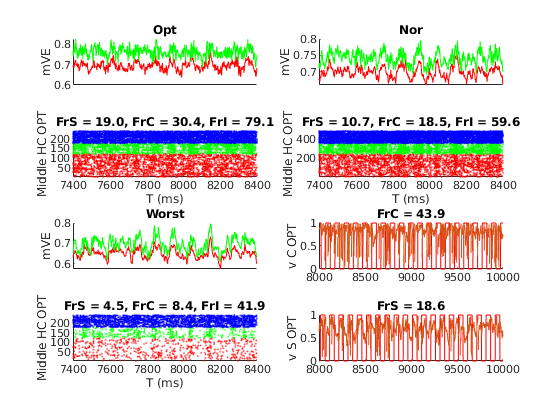

OptE = OD_E==1;           OptI = OD_I==1;
WorstE = OD_E==3;         WorstI = OD_I==3;
NorE = OD_E==2 | OD_E==4; NorI = OD_I==2 | OD_I==4;

MidColS = NnS.X>=1.25*n_S_HC & NnS.X<=1.75*n_S_HC;
MidRowS = NnS.Y>=1.25*n_S_HC & NnS.Y<=1.75*n_S_HC;
MidHCS = MidColS & MidRowS;
MidColC = NnC.X>=1.25*n_C_HC & NnC.X<=1.75*n_C_HC;
MidRowC = NnC.Y>=1.25*n_C_HC & NnC.Y<=1.75*n_C_HC;
MidHCC = MidColC & MidRowC;
MidHCE = [MidHCS, MidHCC];

MidColI = NnI.X>=1.25*n_I_HC & NnI.X<=1.75*n_I_HC;
MidRowI = NnI.Y>=1.25*n_I_HC & NnI.Y<=1.75*n_I_HC;
MidHCI= MidColI & MidRowI;

SOpt = find(OptE & ~EcplxInd);
scatterSOpt = find(ismember(SpE(:,1), SOpt));
[~,SOpt_Ind] = ismember(SpE(scatterSOpt,1),scatterSOpt);
FrSOpt = length(SpE(scatterSOpt,2))/(T/1e3)/length(SOpt);

COpt = find(OptE & EcplxInd);
scatterCOpt = find(ismember(SpE(:,1), COpt));
[~,COpt_Ind] = ismember(SpE(scatterCOpt,1),scatterCOpt);
FrCOpt = length(SpE(scatterCOpt,2))/(T/1e3)/length(COpt);

ShowWin = [7400 8400];
figure('Name','Domain Range')
OD1E = find(OptE & MidHCE);
OD1S = find(OptE & MidHCE & (~EcplxInd));
OD1C = find(OptE & MidHCE & (EcplxInd));
OD1I = find(OptI & MidHCI);
scatter1S = find(ismember(SpE(:,1),OD1S));
scatter1C = find(ismember(SpE(:,1),OD1C));
scatter1I = find(ismember(SpI(:,1),OD1I));
[~,OD1S_Ind] = ismember(SpE(scatter1S,1),OD1S);
[~,OD1C_Ind] = ismember(SpE(scatter1C,1),OD1C);
[~,OD1I_Ind] = ismember(SpI(scatter1I,1),OD1I);
subplot 423
hold on
scatter(SpE(scatter1S,2),OD1S_Ind,0.5,'r.')
scatter(SpE(scatter1C,2),OD1C_Ind+max(OD1S_Ind),0.5,'g.')
scatter(SpI(scatter1I,2),OD1I_Ind+length(OD1E),0.5,'b.');  
FrS1 = length(SpE(scatter1S,2))/(T/1e3)/length(OD1S);
FrC1 = length(SpE(scatter1C,2))/(T/1e3)/length(OD1C);
FrI1 = length(SpI(scatter1I,2))/(T/1e3)/length(OD1I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS1,FrC1,FrI1))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 421
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD1S,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD1C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

OD2E = find(NorE & MidHCE);
OD2S = find(NorE & MidHCE & (~EcplxInd));
OD2C = find(NorE & MidHCE & (EcplxInd));
OD2I = find(NorI & MidHCI);
scatter2S = find(ismember(SpE(:,1),OD2S));
scatter2C = find(ismember(SpE(:,1),OD2C));
scatter2I = find(ismember(SpI(:,1),OD2I));
[~,OD2S_Ind] = ismember(SpE(scatter2S,1),OD2S);
[~,OD2C_Ind] = ismember(SpE(scatter2C,1),OD2C);
[~,OD2I_Ind] = ismember(SpI(scatter2I,1),OD2I);
subplot 424
hold on
scatter(SpE(scatter2S,2),OD2S_Ind,0.5,'r.')
scatter(SpE(scatter2C,2),OD2C_Ind+max(OD2S_Ind),0.5,'g.')
scatter(SpI(scatter2I,2),OD2I_Ind+length(OD2E),0.5,'b.');  
FrS2 = length(SpE(scatter2S,2))/(T/1e3)/length(OD2S);
FrC2 = length(SpE(scatter2C,2))/(T/1e3)/length(OD2C);
FrI2 = length(SpI(scatter2I,2))/(T/1e3)/length(OD2I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS2,FrC2,FrI2))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 422
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD2E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD2C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Nor')
xlim(ShowWin)

OD3E = find(WorstE & MidHCE);
OD3S = find(WorstE & MidHCE & (~EcplxInd));
OD3C = find(WorstE & MidHCE & (EcplxInd));
OD3I = find(WorstI & MidHCI);
scatter3S = find(ismember(SpE(:,1),OD3S));
scatter3C = find(ismember(SpE(:,1),OD3C));
scatter3I = find(ismember(SpI(:,1),OD3I));
[~,OD3S_Ind] = ismember(SpE(scatter3S,1),OD3S);
[~,OD3C_Ind] = ismember(SpE(scatter3C,1),OD3C);
[~,OD3I_Ind] = ismember(SpI(scatter3I,1),OD3I);
subplot 427
hold on
scatter(SpE(scatter3S,2),OD3S_Ind,0.5,'r.')
scatter(SpE(scatter3C,2),OD3C_Ind+max(OD3S_Ind),0.5,'g.')
scatter(SpI(scatter3I,2),OD3I_Ind+length(OD3E),0.5,'b.');  
FrS3 = length(SpE(scatter3S,2))/(T/1e3)/length(OD3S);
FrC3 = length(SpE(scatter3C,2))/(T/1e3)/length(OD3C);
FrI3 = length(SpI(scatter3I,2))/(T/1e3)/length(OD3I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS3,FrC3,FrI3))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 425
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD3E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD3C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

% subplot 427
% hist(SpE(ismember(SpE(:,1),find(NorE & MidHCE)),2),0:1:T)
% xlabel('T (ms)'); ylabel('Spike count for all E cells')
% axis tight
% xlim(ShowWin)
% subplot 425
% plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
% ylabel('mVE')
% set(gca,'xtick','')
% xlim(ShowWin)
tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
subplot 426
hold on
NeuInd = OD1C(5);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E1 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrC = %.1f',Fr1E1))
ylabel('v C OPT')
subplot 428
hold on
NeuInd = OD1S(1);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E2 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrS = %.1f',Fr1E2))
ylabel('v S OPT')

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);
% hist(SpE(ismember(SpE(:,1),OptOne),2),0:1:T)

### Plot Spatial maps: Plot

WinSize = 9000;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));

tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
OnOffmV = ~logical(floor(mod(...
                             repmat(PhaseE, 1, WinNum) + repmat(tCorrect(1:end-1), N_E, 1), ...
                             tMod)/MaxOnPhase));
OnOffSpE =  ~logical(floor(mod(...
                               PhaseE(SpE(:,1)) - T + SpE(:,2),...
                               tMod)/MaxOnPhase));

% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

% NnS.X = NnE.X(~EcplxInd); NnS.Y = NnE.Y(~EcplxInd);
% NnC.X = NnE.X(EcplxInd); NnC.Y = NnE.Y(EcplxInd);

FrERan = [3 48];
mVERan = [0.63 0.78];

Figure for ONOFF

First create an onoff vec for each spike

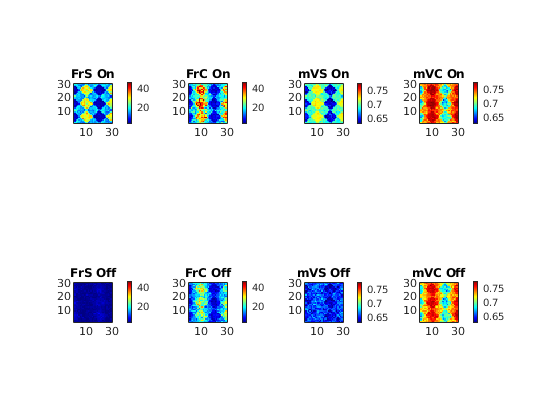

hFrVOnOff = figure('Name','Field_f&V');
% Firing rates:S
subplot 241
ESPinWinOn = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & OnOffSpE;
SpEGoodOn = SpE(ESPinWinOn,1);
[SpCNOn, SpCIOn] = groupcounts(SpEGoodOn);
FrEOn_temp = zeros(N_E,1);
FrEOn_temp(SpCIOn) = SpCNOn*1e3/(EffSize/2);
[FrSOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOnPixMat); title('FrS On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 245
ESPinWinOff = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & ~OnOffSpE;
SpEGoodOff = SpE(ESPinWinOff,1);
[SpCNOff, SpCIOff] = groupcounts(SpEGoodOff);
FrEOff_temp = zeros(N_E,1);
FrEOff_temp(SpCIOff) = SpCNOff*1e3/(EffSize/2);
[FrSOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOffPixMat); title('FrS Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

% Firing rates: C
subplot 242
[FrCOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOnPixMat); title('FrC On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 246
[FrCOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOffPixMat); title('FrC Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
% mVs: S
OnmVPhase = double(OnOffmV);
OnmVPhase(~OnOffmV) = nan;
mVEOn = mVE; mVEOn = mVEOn.*OnmVPhase;
mVEOn_temp = nanmean(mVEOn(:,SmallWinRange),2);

subplot 243
[mVSOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOnPixMat); title('mVS On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

OffmVPhase = double(~OnOffmV);
OffmVPhase(OnOffmV) = nan;
mVEOff = mVE; mVEOff = mVEOff.*OffmVPhase;
mVEOff_temp = nanmean(mVEOff(:,SmallWinRange),2);

subplot 247
[mVSOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOffPixMat); title('mVS Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

% mVs: C
subplot 244
[mVCOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOnPixMat); title('mVC On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

subplot 248
[mVCOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOffPixMat); title('mVC Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)



% % mGs
% subplot 243
% GEEOn = GE_E; GEEOn = GEEOn.*OnmVPhase;
% GEEOn_temp = nanmean(GEEOn(:,SmallWinRange),2);
% [GEEOnPixMat,~] = NeuVec2Pixel(GEEOn_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEEOnPixMat); title('GEE On')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])
% 
% subplot 247
% GEEOff = GE_E; GEEOff = GEEOff.*OffmVPhase;
% GEEOff_temp = nanmean(GEEOff(:,SmallWinRange),2);
% [GEEOffPixMat,~] = NeuVec2Pixel(GEEOff_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEEOffPixMat); title('GEE Off')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])
% 
% subplot 244
% GEIOn = GE_I; GEIOn = GEIOn.*OnmVPhase;
% GEIOn_temp = nanmean(GEIOn(:,SmallWinRange),2);
% [GEIOnPixMat,~] = NeuVec2Pixel(GEIOn_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEIOnPixMat); title('GEI On')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])
% 
% subplot 248
% GEIOff = GE_I; GEIOff = GEIOff.*OffmVPhase;
% GEIOff_temp = nanmean(GEIOff(:,SmallWinRange),2);
% [GEIOffPixMat,~] = NeuVec2Pixel(GEIOff_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEIOffPixMat); title('GEI Off')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])

Figure for All Average

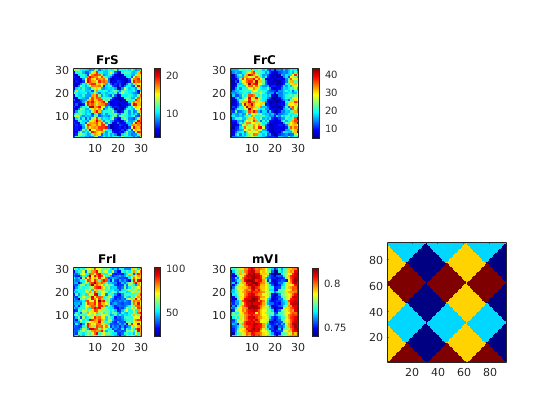

hFrVAll = figure('Name','Field_f&V');
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
%FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

subplot 231
[FrSPixMat,NnSPixel] = NeuVec2Pixel(FrE_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSPixMat); title('FrS')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar
subplot 232
[FrCPixMat,NnCPixel] = NeuVec2Pixel(FrE_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCPixMat); title('FrC')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

% Orientation domain
% subplot 233
% imagesc(OD_EMap);axis square
% set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

Complex % Simple spikes

% end of 500ms plot
OPTC = find(OD_E == 1 & EcplxInd);
OPTS = find(OD_E == 1 & ~EcplxInd);
WORST = find(OD_E == 3);
MID = find(OD_E == 2 | OD_E == 4);
hSpCount = figure('Name','SpCountE')

hSpCount =   Figure (17: SpCountE) with properties:

      Number: 17
        Name: 'SpCountE'
       Color: [0.9400 0.9400 0.9400]
    Position: [1761 1399 560 420]
       Units: 'pixels'

  Show all properties


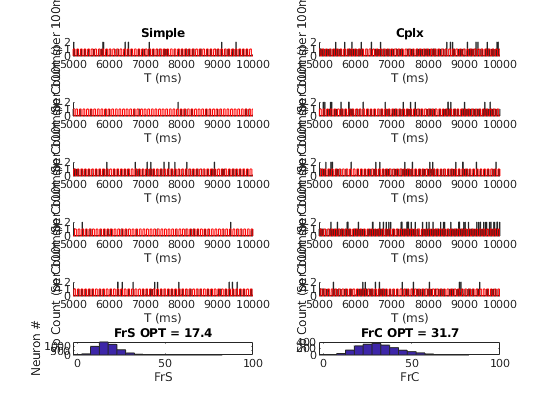

USE = [1,50,300,1000 1500];
for subInd = 1:5
    subplot(6,2,2*subInd-1)
    NeuInd = OPTS(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-T/LGNFreq T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    if subInd ==1
        title('Simple')
    end
    
    subplot(6,2,2*subInd)
    NeuInd = OPTC(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-T/LGNFreq T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    
    if subInd ==1
        title('Cplx')
    end
    
end
OPTS = OptE & ~EcplxInd;
OPTC = OptE & EcplxInd;
subplot(6,2,11)   
hist(FrE_temp(OPTS),0:5:80)
title(sprintf('FrS OPT = %.1f', mean(FrE_temp(OPTS))))
xlabel('FrS'); ylabel('Neuron #')
subplot(6,2,12)   
hist(FrE_temp(OPTC),0:5:80)
title(sprintf('FrC OPT = %.1f', mean(FrE_temp(OPTC))))
xlabel('FrC')

%save('DriveWkSp.mat')

## MF linear equation for pixels: 1 Matrices

clear ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
      OffmVPhase OnmVPhase OnOffmV OnOffSpE...
      SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood...
      mVE mVEOff mVEOn mVI

PixNum = NPixX*N_HC * NPixY*N_HC;
% First, get connectivity matrix between Pixels
C_SS_Pixel_Us = zeros(PixNum); C_CS_Pixel_Us = zeros(PixNum);
C_SC_Pixel_Us = zeros(PixNum); C_CC_Pixel_Us = zeros(PixNum);
C_SI_Pixel_Us = zeros(PixNum); C_CI_Pixel_Us = zeros(PixNum);
C_IS_Pixel_Us = zeros(PixNum); C_IC_Pixel_Us = zeros(PixNum);
C_II_Pixel_Us = zeros(PixNum);
% look into std as well
% C_EE_Pixelstd = zeros(PixNum);
% C_EI_Pixelstd = zeros(PixNum);
% C_IE_Pixelstd = zeros(PixNum);
% C_II_Pixelstd = zeros(PixNum);
tic
AA = PixNum;
parfor PixIndPost = 1:AA
    for PixIndPre = 1:AA
        C_SS_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_SS_Fix_Bd(NnSPixel.Vec == PixIndPost, NnSPixel.Vec == PixIndPre),2));
        C_SC_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_SC_Fix_Bd(NnSPixel.Vec == PixIndPost, NnCPixel.Vec == PixIndPre),2));
        C_CS_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_CS_Fix_Bd(NnCPixel.Vec == PixIndPost, NnSPixel.Vec == PixIndPre),2));
        C_CC_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_CC_Fix_Bd(NnCPixel.Vec == PixIndPost, NnCPixel.Vec == PixIndPre),2));
        C_SI_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_SI_Fix_Bd(NnSPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_CI_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_CI_Fix_Bd(NnCPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IS_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_IS_Fix_Bd(NnIPixel.Vec == PixIndPost, NnSPixel.Vec == PixIndPre),2));
        C_IC_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_IC_Fix_Bd(NnIPixel.Vec == PixIndPost, NnCPixel.Vec == PixIndPre),2));
        C_II_Pixel_Us(PixIndPost,PixIndPre) = mean(sum(C_II_Fix_Bd(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
%         C_EE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EE_Fix_Bd(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
%         C_EI_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EI_Fix_Bd(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
%         C_IE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_IE_Fix_Bd(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
%         C_II_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_II_Fix_Bd(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
    end    
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


toc

Elapsed time is 49.330843 seconds.


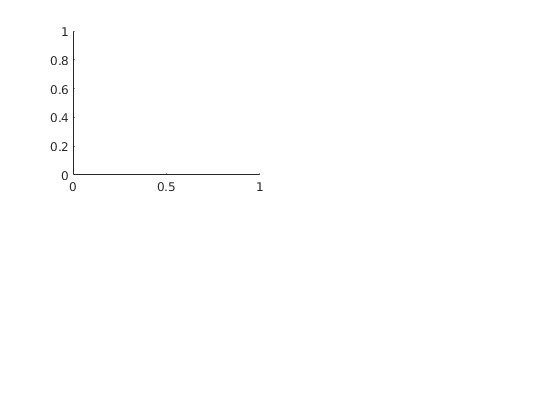

% C_EE_Pixel_Us = sparse(C_EE_Pixel);
% C_IE_Pixel_Us = sparse(C_IE_Pixel);
% C_EI_Pixel_Us = sparse(C_EI_Pixel);
% C_II_Pixel_Us = sparse(C_II_Pixel);
save([SaveFolder 'ConnPixel.mat'], 'C_SS_Pixel_Us','C_CS_Pixel_Us',...
                                   'C_SC_Pixel_Us','C_CC_Pixel_Us',...
                                   'C_SI_Pixel_Us','C_CI_Pixel_Us',...
                                   'C_IS_Pixel_Us','C_IC_Pixel_Us',...
                                   'C_II_Pixel_Us')
% Present connectivity mats
figure
subplot 221

imagesc(C_SS_Pixel_Us)

Unrecognized function or variable 'C_SS_Pixel'.

colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_CS_Pixel_Us)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_CI_Pixel_Us)
axis square
colorbar
title('std/mean')

## Clear redundant variables for memory

clear C_EE C_EE_Fix_Bd C_EI C_EI_Fix_Bd...
      C_IE C_IE_Fix_Bd C_II C_II_Fix_Bd...
      ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
      OffmVPhase OnmVPhase OnOffmV OnOffSpE...
      SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood...
      mVE mVEOff mVEOn mVI

MF linear equation for pixels: 2 MF Eqns

load([SaveFolder 'ConnPixel.mat'])

PixNum = NPixX*N_HC * NPixY*N_HC;
FrSPixVec    = reshape(FrSPixMat,  PixNum,1);
FrSOnPixVec  = reshape(FrSOnPixMat,PixNum,1);
FrSOffPixVec = reshape(FrSOffPixMat,PixNum,1);
FrCPixVec    = reshape(FrCPixMat,  PixNum,1);
FrCOnPixVec  = reshape(FrCOnPixMat,PixNum,1);
FrCOffPixVec = reshape(FrCOffPixMat,PixNum,1);
FrIPixVec    = reshape(FrIPixMat,  PixNum,1);

mVSOnPixVec  = reshape(mVSOnPixMat,PixNum,1);
mVSOffPixVec = reshape(mVSOffPixMat,PixNum,1);
mVCOnPixVec  = reshape(mVCOnPixMat,PixNum,1);
mVCOffPixVec = reshape(mVCOffPixMat,PixNum,1);
mVIPixVec = reshape(mVIPixMat,PixNum,1);

% Precompute LGN and L6
lambda_SOn_Pixel = zeros(PixNum,1);
lambda_SOff_Pixel = zeros(PixNum,1);
lambda_COn_Pixel = zeros(PixNum,1);
lambda_COff_Pixel = zeros(PixNum,1);
L6E_Pixel = zeros(PixNum,1);
L6I_Pixel = zeros(PixNum,1);
for PixInd = 1:PixNum
    lambda_EOn_Pixel(PixInd)  = mean(lambda_EOn_drive(NnEPixel.Vec == PixInd));
    lambda_EOff_Pixel(PixInd) = mean(lambda_EOff_drive(NnEPixel.Vec == PixInd));
    L6E_Pixel(PixInd) = mean(rE_L6_Drive(NnEPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive_Pre;

% Setup preused Firing rates for off E
%FrPreUseDim = find(lambda_EOff_Pixel<0.08) + PixNum;
FrPreUseDim = (1:PixNum) + PixNum;
%FrPreUse = FrEOffPixVec(FrPreUseDim - PixNum); 
FrPreUse = FrEOffLIF(FrPreUseDim - PixNum); 
%FrPreUse = [];


% Mats
MatEE = (S_EE*(1-p_EEFail))*full(C_EE_Pixel_Us); % Need Ref here??
MatEI = S_EI *              full(C_EI_Pixel_Us);
MatIE = S_IE *              full(C_IE_Pixel_Us).*(Ve-repmat(mVIPixVec,1,PixNum));
MatII = S_II *              full(C_II_Pixel_Us).*(Vi-repmat(mVIPixVec,1,PixNum));
ConnMat = [MatEE.*(Ve-repmat(mVEOnPixVec,1,PixNum))/2 , MatEE.*(Ve-repmat(mVEOnPixVec,1,PixNum))/2 , MatEI.*(Vi-repmat(mVEOnPixVec,1,PixNum));
           MatEE.*(Ve-repmat(mVEOffPixVec,1,PixNum))/2, MatEE.*(Ve-repmat(mVEOffPixVec,1,PixNum))/2, MatEI.*(Vi-repmat(mVEOffPixVec,1,PixNum));
           MatIE/2                                    , MatIE/2                                    , MatII];
% Leak On/Off
LeakEOn  = gL_E * (0-mVEOnPixVec)  * 1e3;
LeakEOff = gL_E * (0-mVEOffPixVec) * 1e3;
LeakI =    gL_I * (0-mVIPixVec)    * 1e3;
LeakV = [LeakEOn;LeakEOff;LeakI];
% Ext
ExtEOn  = (lambda_EOn_Pixel*S_Elgn  + rE_amb*S_amb + L6E_Pixel*S_EL6).*(Ve-mVEOnPixVec ) * 1e3;
ExtEOff = (lambda_EOff_Pixel*S_Elgn + rE_amb*S_amb + L6E_Pixel*S_EL6).*(Ve-mVEOffPixVec) * 1e3;
ExtI =    (lambda_I_Pixel*S_Ilgn    + rI_amb*S_amb + L6I_Pixel*S_IL6).*(Ve-mVIPixVec)    * 1e3;
ExtV = [ExtEOn;ExtEOff;ExtI];
% Ref Vec
RefEOn = 1-FrEOnPixVec*tau_ref/1e3;
RefEOff = 1-FrEOffPixVec*tau_ref/1e3;
RefI = 1-FrIPixVec*tau_ref/1e3;
RefM = diag([RefEOn;RefEOff;RefI]);
% L4 Frs
Fr_L4 = [FrEOnPixVec; FrEOffPixVec; FrIPixVec];

% MF Equations:
%Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
tic
    if isempty(FrPreUse)
    Fr_MFinv = (sparse(eye(3*PixNum))-RefM*ConnMat) \ (RefM * ( ExtV + LeakV));
    else
        FrPreVec = zeros(PixNum*3,1); FrPreVec(FrPreUseDim) = FrPreUse;
        DimAll = 1:PixNum*3; FrminusDim = DimAll(~ismember(DimAll,FrPreUse));
        FrPreReplace = RefM*ConnMat * FrPreVec; 
        % Now compute in the subspace
        FrPreMinus = FrPreReplace(FrminusDim);
        RefMMinus  = RefM(FrminusDim, FrminusDim);
        ConnMatMinus = ConnMat(FrminusDim, FrminusDim);
        ExtVMinus = ExtV(FrminusDim);
        LeakVMinus = LeakV(FrminusDim);
        Fr_MFinvMinus = (sparse(eye(length(FrminusDim)))-RefMMinus*ConnMatMinus) \ ...
                        (RefMMinus * ( ExtVMinus + LeakVMinus) + FrPreMinus);
        % make up MF output            
        Fr_MFinv = zeros(PixNum*3,1);   
        Fr_MFinv(FrminusDim) = Fr_MFinvMinus; Fr_MFinv(FrPreUseDim) = FrPreUse; 
    end
toc
% Err
FrErr = Fr_MFinv - Fr_L4;

Scatter MF Rslt

SC = Fr_MFinv;
figure('Name','FrCompare')
subplot 331
hold on
scatter(FrEOnPixVec, SC(1:900),'r.')
plot(1:120, 1:120)
axis([0 60 0 60]);axis square
xlabel('FrEOn NW'); ylabel('FrEOn MF')
subplot 332
hold on
scatter(FrEOffPixVec, SC(901:1800),'m.')
plot(1:120, 1:120)
axis([-10 15 -10 15]); axis square
xlabel('FrEOff NW'); ylabel('FrEOff MF')
subplot 333
hold on
scatter(FrIPixVec, SC(1801:2700),'b.')
plot(1:120, 1:120)
axis([40 120 40 120]); axis square
xlabel('FrI NW'); ylabel('FrI MF')

subplot 334
ShowField(SC(1:PixNum), 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrEOn MF')
caxis([0 55])

subplot 335
ShowField(SC(PixNum+1:2*PixNum), 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrEOff MF')
caxis([-6 13])

subplot 336
ShowField(SC(2*PixNum+1:3*PixNum), 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrI MF')
caxis([30 120])

subplot 337
ShowField(FrEOnPixVec, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrEOn NW')
caxis([0 55])

subplot 338
ShowField(FrEOffPixVec, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrEOff NW')
caxis([-6 13])

subplot 339
ShowField(FrIPixVec, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrI NW')
caxis([30 120])

Plot MF Rslt

EPixRange = [0 35];
IPixRange = [10 120]

figure('Name','MF and Real Fr')
a1 = subplot (241);
PS = get(a1,'Position');
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a1,'Position',PS)
caxis(EPixRange);

a5 = subplot (245);
PS = get(a5,'Position');
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a5,'Position',PS)
caxis(IPixRange);

a2 = subplot (242);
PS = get(a2,'Position');
FrEPixMat_MF = (reshape(Fr_MFinv(1:PixNum),NPixY*N_HC,NPixX*N_HC) + ...
               reshape(Fr_MFinv(PixNum+1:2*PixNum),NPixY*N_HC,NPixX*N_HC))/2;
imagesc(FrEPixMat_MF); title('FrE_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a2,'Position',PS)
caxis(EPixRange);

a6 = subplot (246);
PS = get(a6,'Position');
FrIPixMat_MF = reshape(Fr_MFinv(2*PixNum+1:end),NPixY*N_HC,NPixX*N_HC)
imagesc(FrIPixMat_MF); title('FrI_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a6,'Position',PS)
caxis(IPixRange);

subplot 243
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 247
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

subplot 244
hold on
plot(1:120, 1:120)
scatter(FrEPixVec,(Fr_MFinv(1:PixNum) + Fr_MFinv(PixNum+1:2*PixNum))/2,'r.')
axis([EPixRange EPixRange])
axis square
xlabel('FrE'); ylabel('FrE_{MF}')

subplot 248
hold on
plot(1:120, 1:120)
scatter(FrIPixVec,Fr_MFinv(2*PixNum+1:end),'b.')
 axis([IPixRange IPixRange])
axis square
xlabel('FrI'); ylabel('FrI_{MF}')

Result not very good. On the other hand, should concern real input since we are only averaging from 25/8 neurons?

Check code: Mistakes in row and column?